# Task 3

## Feature matching from a .bagfile

Change this value to 1 if you want to display every frames features

dispay_every_frame = 0;

First we load the feed from the .bag file according to the lab instructions

bagselect = rosbag("../lab2.bag");
topicleftimg = "/spot/camera/frontleft/image";
selectleft = select(bagselect,"Topic",topicleftimg);
leftimglist = readMessages(selectleft);
topicrightimg = "/spot/camera/frontright/image";
selectright = select(bagselect,"Topic",topicrightimg);
rightimglist = readMessages(selectright);

Declare a feed/context and start counting time/number of features

context = [];
total_features = 0;
non_feature_frames = 0;
before = tic();

Itterate through the feed. If this was online, this would just occur on some frame interrupt.

for n = 1:numel(leftimglist)

Read the images from the fead.

    leftimg = readImage(leftimglist{n});
    rightimg = readImage(rightimglist{n});

Match said images

    [context,features,features1,features2] = feature_match(context,leftimg,rightimg);

If we want to display every frame do so now.

    if dispay_every_frame
        display_at_frame(context,n);
    end

Append number of features to the total feature count

    total_features = total_features+numel(features(:)); % Add the number of elements in the features list
    if 0 == numel(features(:))
        non_feature_frames= non_feature_frames + 1;
    end
end

Get time difference

after = toc(before);

Compute fps and average features per image

fps = numel(leftimglist)/after              

fps = 5.1063

avg_features = total_features/numel(leftimglist)

avg_features = 2.5667

non_feature_frames

non_feature_frames = 109

number_of_frames = numel(leftimglist)

number_of_frames = 240

Now we can visualize the images at a certain timestamp

% Now we can show the image at a certain point in time
% Display the matched images
n = 22

n = 22


Showing the matched images at n = 22
Left image at n = 22


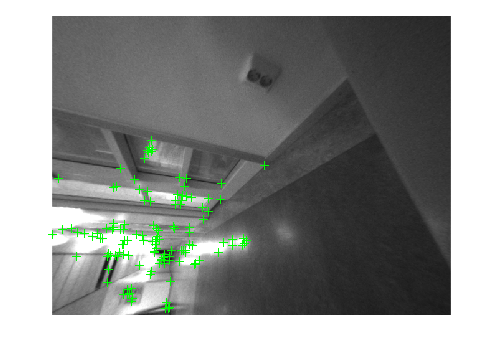

Right image at n = 22


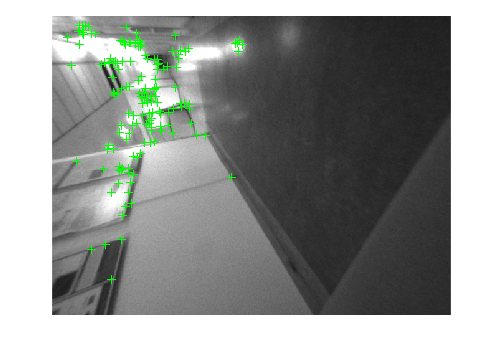

Feature matched images at n = 22


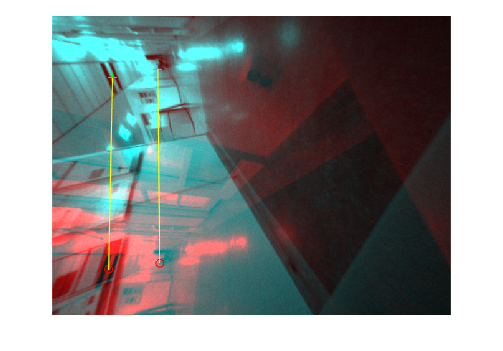

display_at_frame(context,n)

Showing a number of frames is also possible using a for loop, simulating a partial feed.

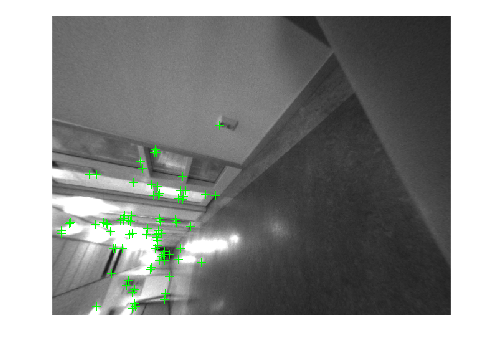


Showing the matched images at n = 1
Left image at n = 1


Right image at n = 1


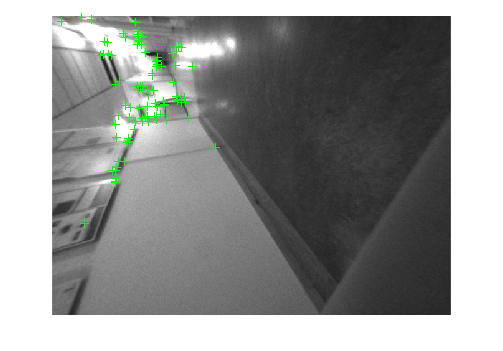

Feature matched images at n = 1


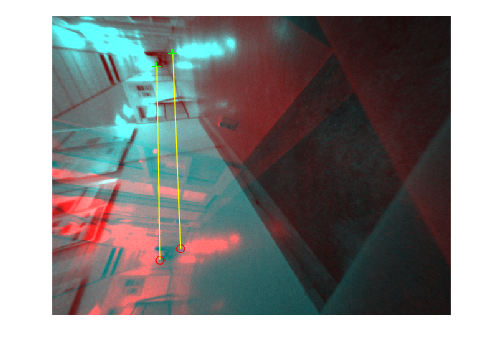


Showing the matched images at n = 2
Left image at n = 2


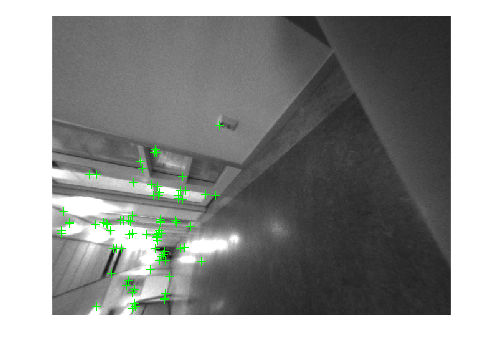

Right image at n = 2


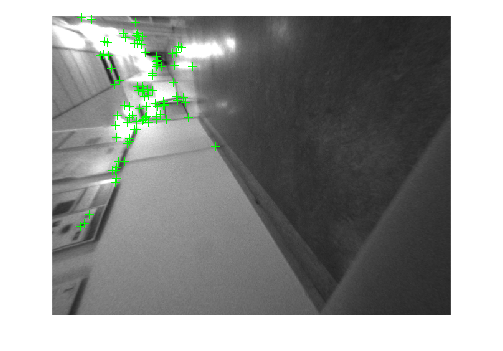

Feature matched images at n = 2


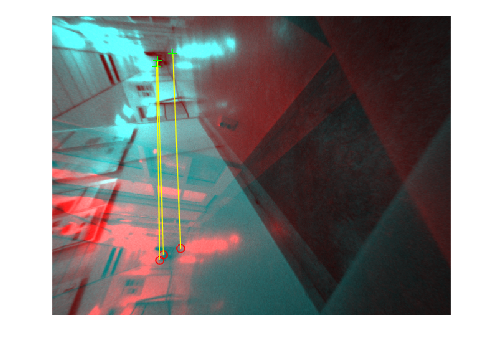


Showing the matched images at n = 3
Left image at n = 3


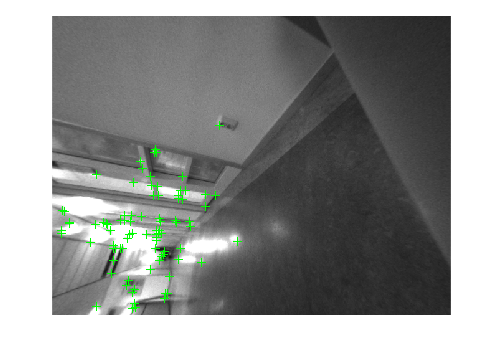

Right image at n = 3


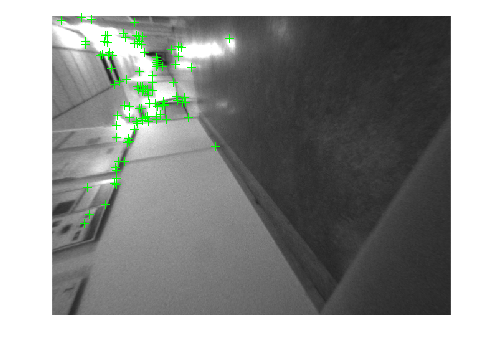

Feature matched images at n = 3


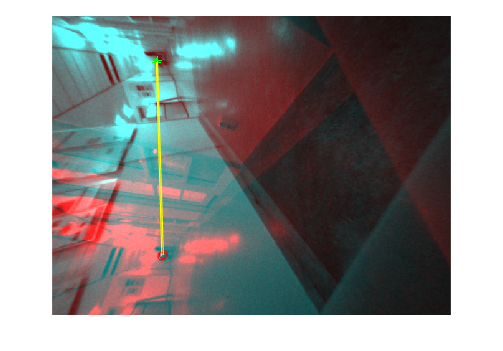

for i = 1:3
    display_at_frame(context,i);
end

Declare a function to display all the relevant images for visualization of feature matching at a given frame.

function display_at_frame(feed,n)
    fprintf("\n===================================\n")
    
    fprintf("Showing the matched images at n = %d\n",n)
    fprintf("Left image at n = %d\n",n)
    imshow(feed(n).img1);
    hold on 
    plot(feed(n).features1);
    hold off
    fprintf("Right image at n = %d\n",n)
    figure
    imshow(feed(n).img2);
    hold on 
    plot(feed(n).features2);
    hold off
    figure
    fprintf("Feature matched images at n = %d\n",n)
    showMatchedFeatures(feed(n).img1,feed(n).img2,feed(n).loc1(feed(n).features(:,1),:),feed(n).loc2(feed(n).features(:,2),:));
    figure
end

#### A coppy of the feature_match function

function [feed,features,featuresa,featuresb] = feature_match_copy(feed,img1, ...
                                                img2, varargin)
    % A function that maches features in 2 images. It returns the current
    % feed ( or context ) the features matched, the features detected in
    % image1, and the feature detected in image b in that order.
    % 
    % The features can be matched using either Harris or the SIFT detector,
    % Allowing the end user to use the optimal one for their usecase.
    % The default feature detector is HARRIS, but if you want to change it
    % to SIFT, then just pass SIFT in as the 4th argument.

    function [args] = parse(vararg)
        % Assume no inputs
        args = "";
        % We only want to handle 1 optional arument
        if (numel(vararg) >= 2)
            % Since we only want to handle a set of different methods we
            % can assume that the method is the first argument
            args = vararg{2};
        end
    end
    [method] = parse(["",varargin{:}]);
    
    if strcmpi(method,"SIFT")
        featuresa = detectSIFTFeatures(img1);
        featuresb = detectSIFTFeatures(img2);
        
    
        % Get feature descriptors
        [features1,loc1] = extractFeatures(img1,featuresa,"Method",method);
        [features2,loc2] = extractFeatures(img2,featuresb,"Method",method);
    else
        featuresa = detectHarrisFeatures(img1);
        featuresb = detectHarrisFeatures(img2);
        
    
        % Get feature descriptors
        [features1,loc1] = extractFeatures(img1,featuresa);
        [features2,loc2] = extractFeatures(img2,featuresb);
    end

    % Match the features using said descriptors
    features = matchFeatures(features1,features2);
    
    % Store the result for later use
    obj = [];
    obj.img1 = img1;
    obj.img2 = img2;
    obj.loc1 = loc1;
    obj.loc2 = loc2;
    obj.features = features;
    obj.features1 = featuresa;
    obj.features2 = featuresb;
    
    % Append the current feature match to the previous matches
    feed = [feed; obj];
end